[a_inst, Fs] = audioread("1_Lisztomania_Inst_-14lufs.mp3",'native');
[a_vox, Fs] =  audioread("1_Lisztomania_Vox_-14lufs.mp3",'native');
[b_inst, Fs] = audioread("7_Countdown_Inst_-14lufs.mp3",'native');
[b_vox, Fs] =  audioread("7_Countdown_Vox_-14lufs.mp3",'native');

TT_a_inst = timetable(a_inst, 'SampleRate', Fs);
TT_a_vox = timetable(a_vox, 'SampleRate', Fs);
TT_b_inst = timetable(b_inst, 'SampleRate', Fs);
TT_b_vox = timetable(b_vox, 'SampleRate', Fs);

save;


保存先:C:\Dropbox\論文\2稿目_音楽振動ナビ\V2実験データ\楽曲スペクトラム表示\matlab.mat



## グラフ描画

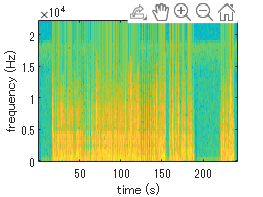

close all;
% figure;
% subplot(2,1,1);
% t = TT_a_vox.Time;
% y = TT_a_vox.a_vox(:,1);
% plot(t, y);
% subplot(2,1,2);

% figure;
% spectrogram(y,[],[],[],Fs,'yaxis');
% set(gca,'yscale','log')
% ax = gca;
% ylim([1 1000])

% plot(TT_b_vox.Time, TT_b_vox.b_vox(:,1));
% t = TT_a_vox.Time;
x = TT_a_vox.a_vox(:,1);
[ X, f, t, S ] = spectrogram( x, 128, 120, 128, Fs );


axis xy
xlabel( 'time (s)' )
ylabel( 'frequency (Hz)' )

set(gca,'yscale','log')
ax = gca;
ylim([1 1000])

imagesc( t, f, pow2db( S ) )


% % パラメーター
% timeLimits = seconds([0 242.0647]); % 秒
% frequencyLimits = [0 100]; % Hz
% overlapPercent = 50;
% 
% %%
% % 対象の信号時間領域へのインデックス
% TT_a_vox_a_vox_1_ROI = TT_a_vox.a_vox(:,1);
% timeValues = TT_a_vox.Properties.RowTimes;
% TT_a_vox_a_vox_1_ROI = timetable(timeValues,TT_a_vox_a_vox_1_ROI,'VariableNames',{'Data'});
% TT_a_vox_a_vox_1_ROI = TT_a_vox_a_vox_1_ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
% 
% % スペクトル推定の計算
% % 以下の関数呼び出しを出力引数なしで実行して結果をプロットします
% [P,F,T] = pspectrum(TT_a_vox_a_vox_1_ROI, ...
%     'spectrogram', ...
%     'FrequencyLimits',frequencyLimits, ...
%     'OverlapPercent',overlapPercent);